# Cart-Pole Discrete Control

## State Space Representation

See "wheeled_balancer_model_eqtns.mlx" and "wheeled_balancer_model.mlx" for derivation of equations of motion and real values of system parameters.

% outputting both the x-position and theta-angle
A = [0    1.0000         0         0
         0   -7.0198   -4.2395         0
         0         0         0    1.0000
         0   86.6165  173.2330         0];
B =[0
    4.2385
         0
  -52.2983];
C = [1 0 0 0; 0 0 0 1];
D = [0;0];
states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
cplant = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)


cplant =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot              0      -7.02     -4.239          0
   theta              0          0          0          1
   theta_dot          0      86.62      173.2          0
 
  B = 
                  u
   x              0
   x_dot      4.239
   theta          0
   theta_dot  -52.3
 
  C = 
                  x      x_dot      theta  theta_dot
   x              1          0          0          0
   theta          0          0          0          1
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.


## Discretization

T = 1/100; % 0.01s, 100Hz
plant = c2d(cplant,T);
[G, H, Cd, Dd] = ssdata(plant)

G =     1.0000    0.0097   -0.0002   -0.0000
         0    0.9322   -0.0411   -0.0002
         0    0.0042    1.0086    0.0100
         0    0.8389    1.7193    1.0086


H =     0.0002
    0.0410
   -0.0026
   -0.5065


Cd =      1     0     0     0
     0     0     0     1


Dd =      0
     0


## Stabilize System with SS Feedback P Control; Discrete

% contrallability/observability
rank(ctrb(G,H)), rank(obsv(G,Cd))

ans = 4

ans = 4

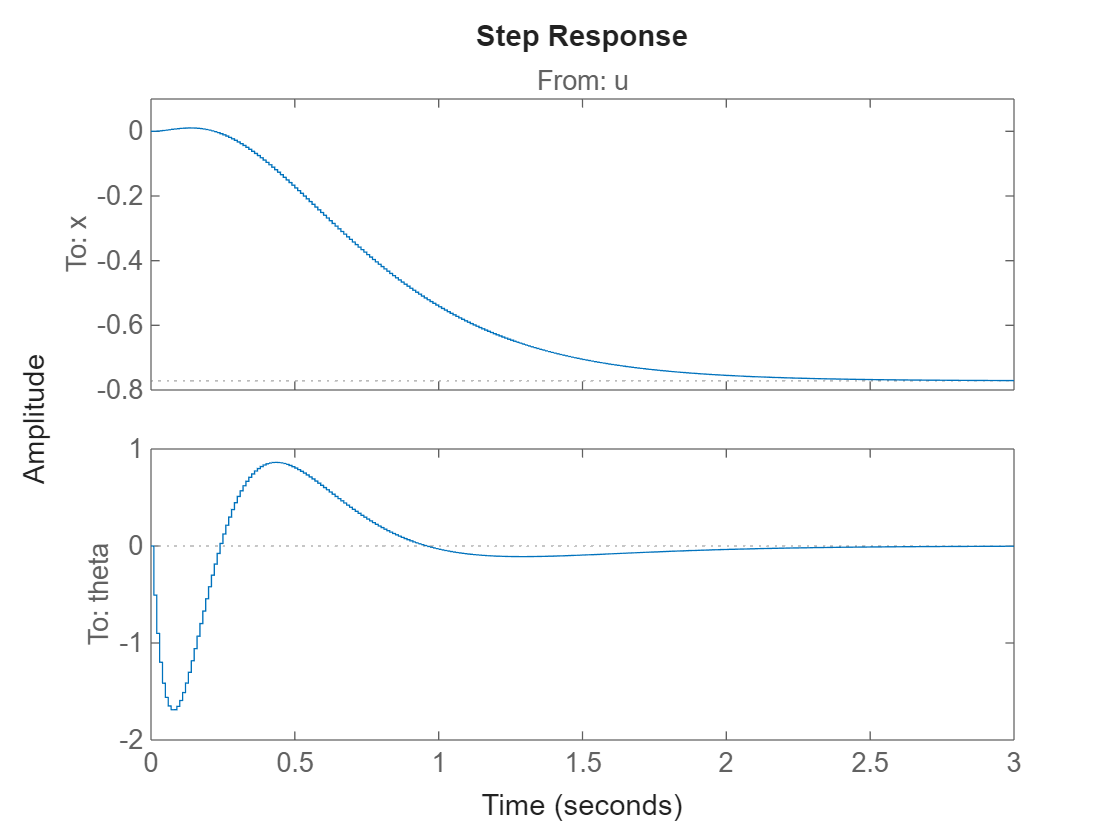


% desired close-loop pole locations:
pc = [-3, -4, -6, -10];
pd = exp(T*pc);

% Feedback controller
K = acker(G,H,pd);

% Closed-loop system
states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
clsys = ss(G-H*K, H, Cd, Dd, T, ...
    'statename',states,'inputname',inputs,'outputname',outputs);
step(clsys)

figure;
gain = Cd*(eye(4) - (G - H*K))^(-1)*H

gain =    -0.7718
   -0.0000


step(clsys/gain(1))

## Stabilize System with SS Feedback PI Control; Discrete

### Theory:

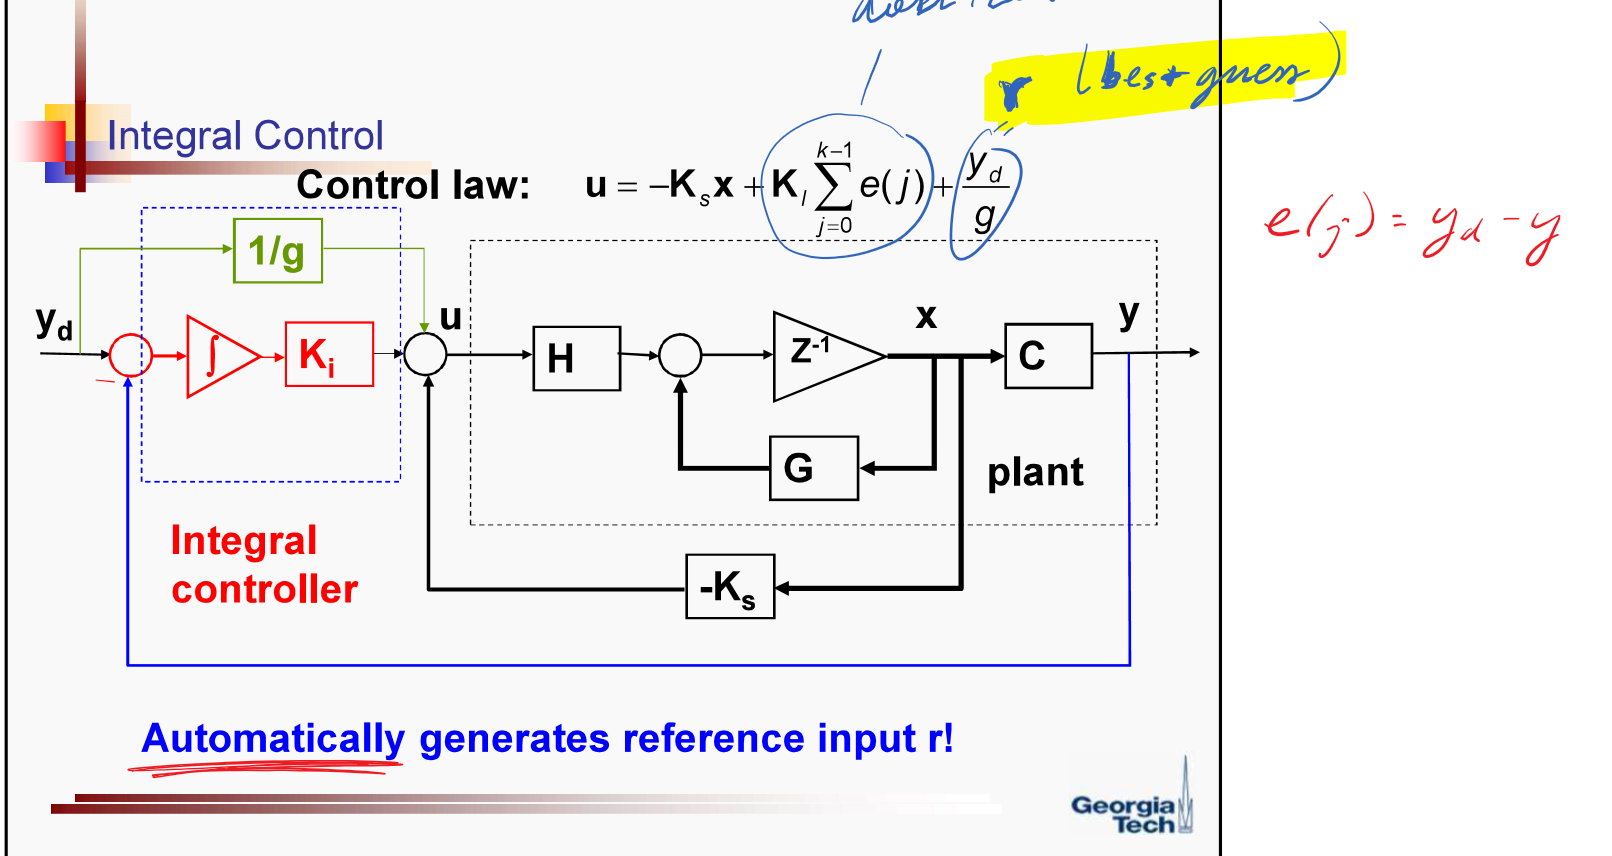

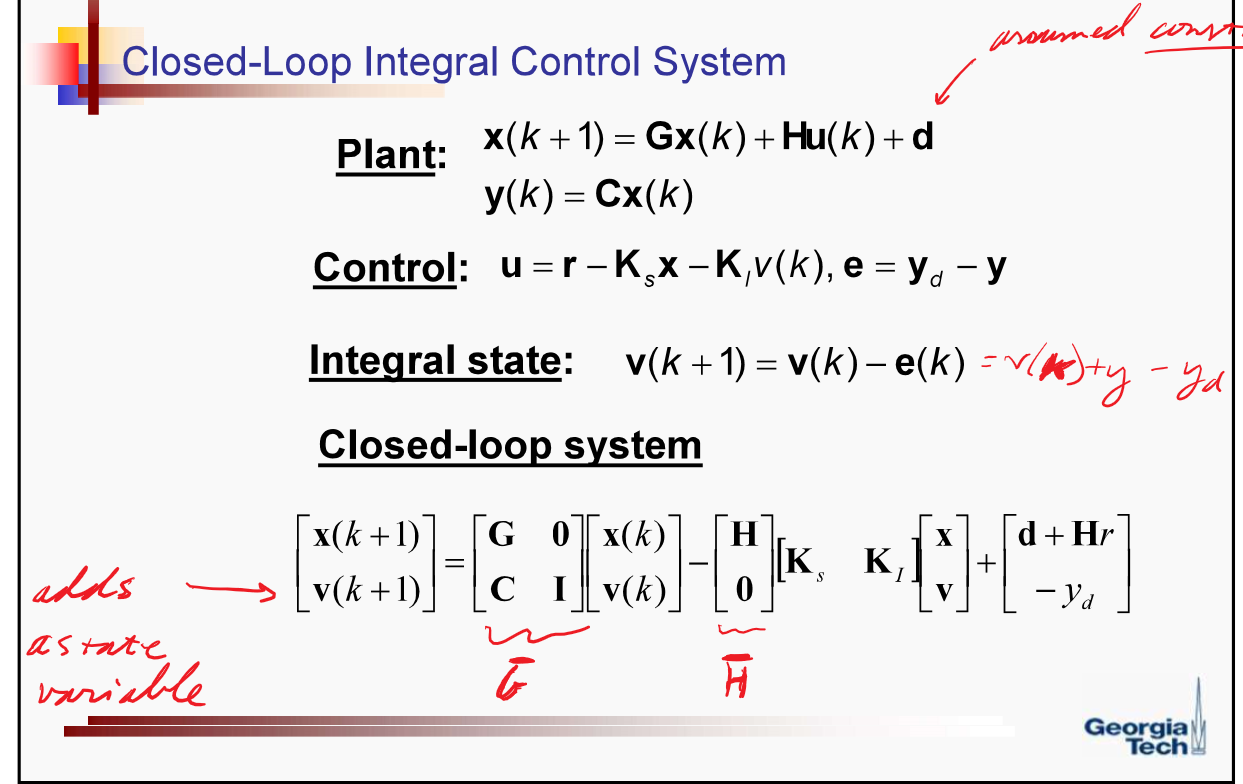

instead of -yd at the end though, defining v(k+1) = v(k) + e(k) so that we invert the signs of yd and C

### Implementation:

Gbar = [G zeros(4,1); -Cd(1,:) 1]

Gbar =     1.0000    0.0097   -0.0002   -0.0000         0
         0    0.9322   -0.0411   -0.0002         0
         0    0.0042    1.0086    0.0100         0
         0    0.8389    1.7193    1.0086         0
   -1.0000         0         0         0    1.0000


Hbar = [H; 0]

Hbar =     0.0002
    0.0410
   -0.0026
   -0.5065
         0


% desired close-loop pole locations:
pc = [-3, -4, -6, -9, -10];
pd = exp(T*pc)

pd =     0.9704    0.9608    0.9418    0.9139    0.9048


K = acker(Gbar, Hbar, pd)

K =   -10.8317   -5.7073  -11.0581   -0.9188    0.1115


Gcl = Gbar - Hbar*K

Gcl =     1.0022    0.0108    0.0021    0.0002   -0.0000
    0.4437    1.1660    0.4120    0.0374   -0.0046
   -0.0277   -0.0104    0.9803    0.0077    0.0003
   -5.4865   -2.0520   -3.8819    0.5432    0.0565
   -1.0000         0         0         0    1.0000


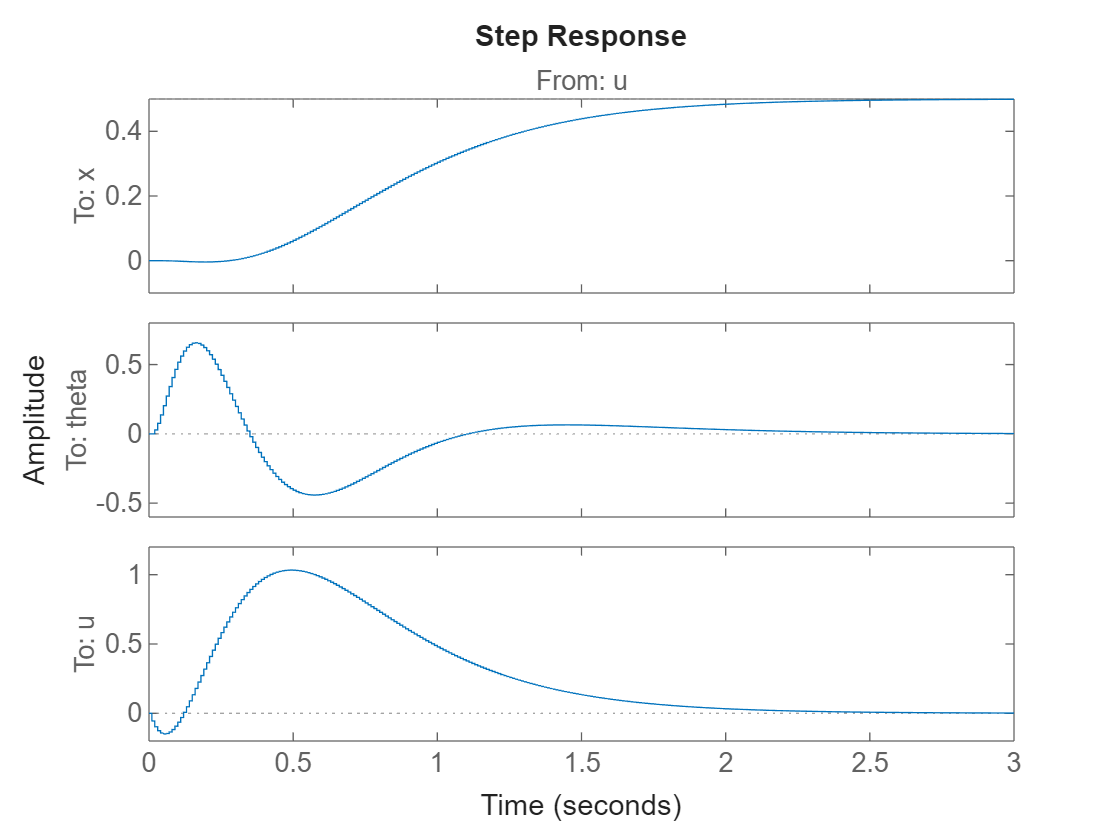

yd = 0.5; r = 0; 
% r is 0 because the error (yd - y) automatically generates the reference input
states = {'x' 'x_dot' 'theta' 'theta_dot' 'integral'};
inputs = {'u'};
outputs = {'x'; 'theta';'u'};
clsys = ss(Gcl, [H*r; yd],[Cd [0;0]; -K],[Dd; 0],T,...
    'statename',states,'inputname',inputs,'outputname',outputs);
step(clsys)

## Stabilize System with FOO Feedback Proportional Control; Discrete

### Theory:

TODO - write up the equations here...

### Implementation:

Gbar = [G zeros(4,1); Cd(1,:) 1]

Gbar =     1.0000    0.0097   -0.0002   -0.0000         0
         0    0.9322   -0.0411   -0.0002         0
         0    0.0042    1.0086    0.0100         0
         0    0.8389    1.7193    1.0086         0
    1.0000         0         0         0    1.0000


Hbar = [H; 0]

Hbar =     0.0002
    0.0410
   -0.0026
   -0.5065
         0


% desired close-loop pole locations:
pc = [-3, -4, -6, -9, -10];
pd = exp(T*pc)

pd =     0.9704    0.9608    0.9418    0.9139    0.9048


K = acker(Gbar, Hbar, pd)

K =   -10.8317   -5.7073  -11.0581   -0.9188   -0.1115


Gcl = Gbar - Hbar*K

Gcl =     1.0022    0.0108    0.0021    0.0002    0.0000
    0.4437    1.1660    0.4120    0.0374    0.0046
   -0.0277   -0.0104    0.9803    0.0077   -0.0003
   -5.4865   -2.0520   -3.8819    0.5432   -0.0565
    1.0000         0         0         0    1.0000


yd = 0.5; r = 0; 
% r is 0 because the error (yd - y) automatically generates the reference input
states = {'x' 'x_dot' 'theta' 'theta_dot' 'integral'};
inputs = {'u'};
outputs = {'x'; 'theta';'u'};
clsys = ss(Gcl, [H*r; -yd],[Cd [0;0]; -K],[Dd; 0],T,...
    'statename',states,'inputname',inputs,'outputname',outputs);
step(clsys)